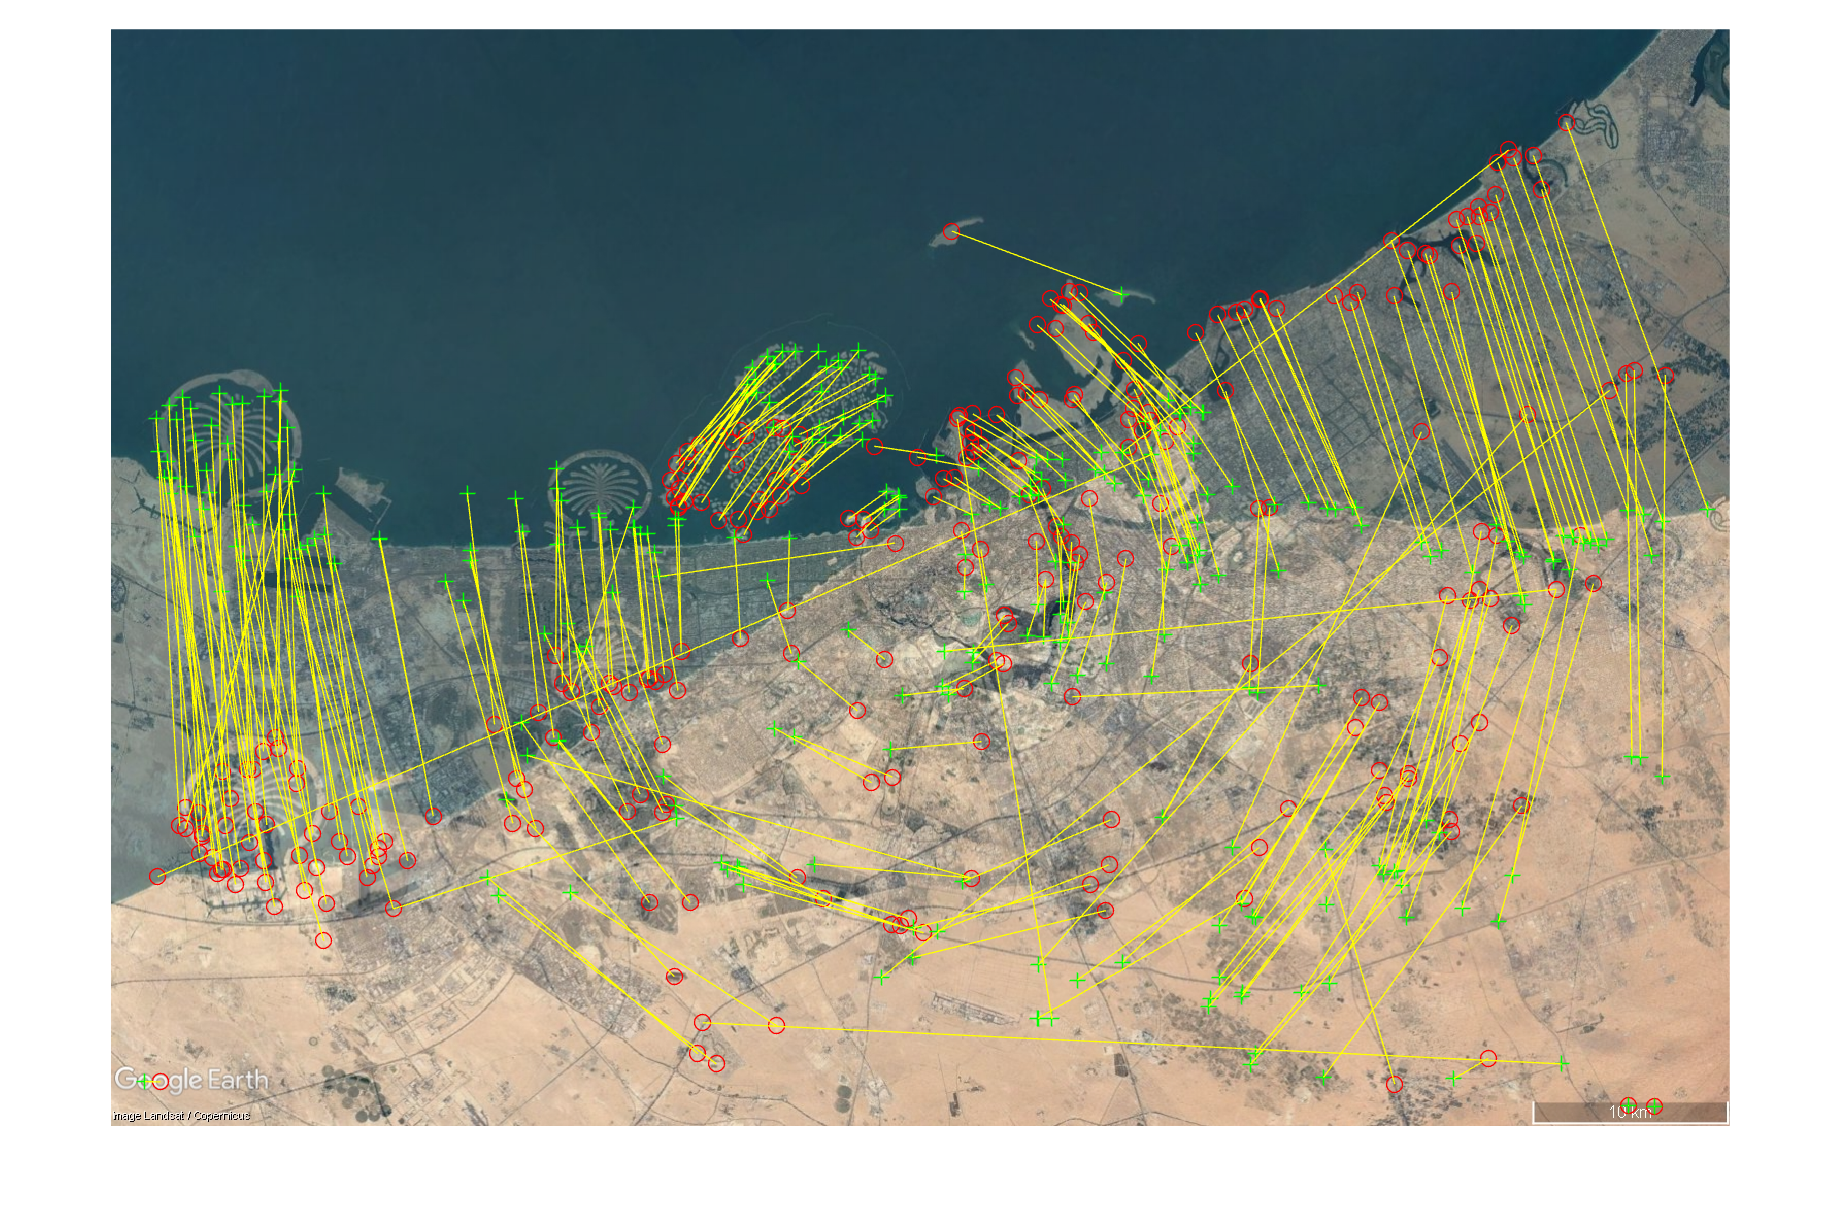

% Get full path to this live‐script
scriptFullPath = matlab.desktop.editor.getActiveFilename;
scriptFolder   = fileparts(scriptFullPath);

% Go up two levels to the project root
projectRoot = fileparts(fileparts(scriptFolder));

% Point at the Moodle dataset folder
% download the dataset from moodle and place it in the root diretory
datasetDir = fullfile(projectRoot, 'datasets_moodle', 'Dubai');

% Build and check image paths
movingPath = fullfile(datasetDir, '12_2015.jpg');
fixedPath  = fullfile(datasetDir, '12_2020.jpg');
assert(isfile(movingPath), 'Cannot find %s', movingPath);
assert(isfile(fixedPath ), 'Cannot find %s', fixedPath);

% Read the images
movingImg = imread(movingPath);
fixedImg  = imread(fixedPath);


regOutput = registerDubaiImages(movingImg,fixedImg);
showMatchedFeatures(movingImg, fixedImg,regOutput.MovingMatchedFeatures, ...
    regOutput.FixedMatchedFeatures, "blend");

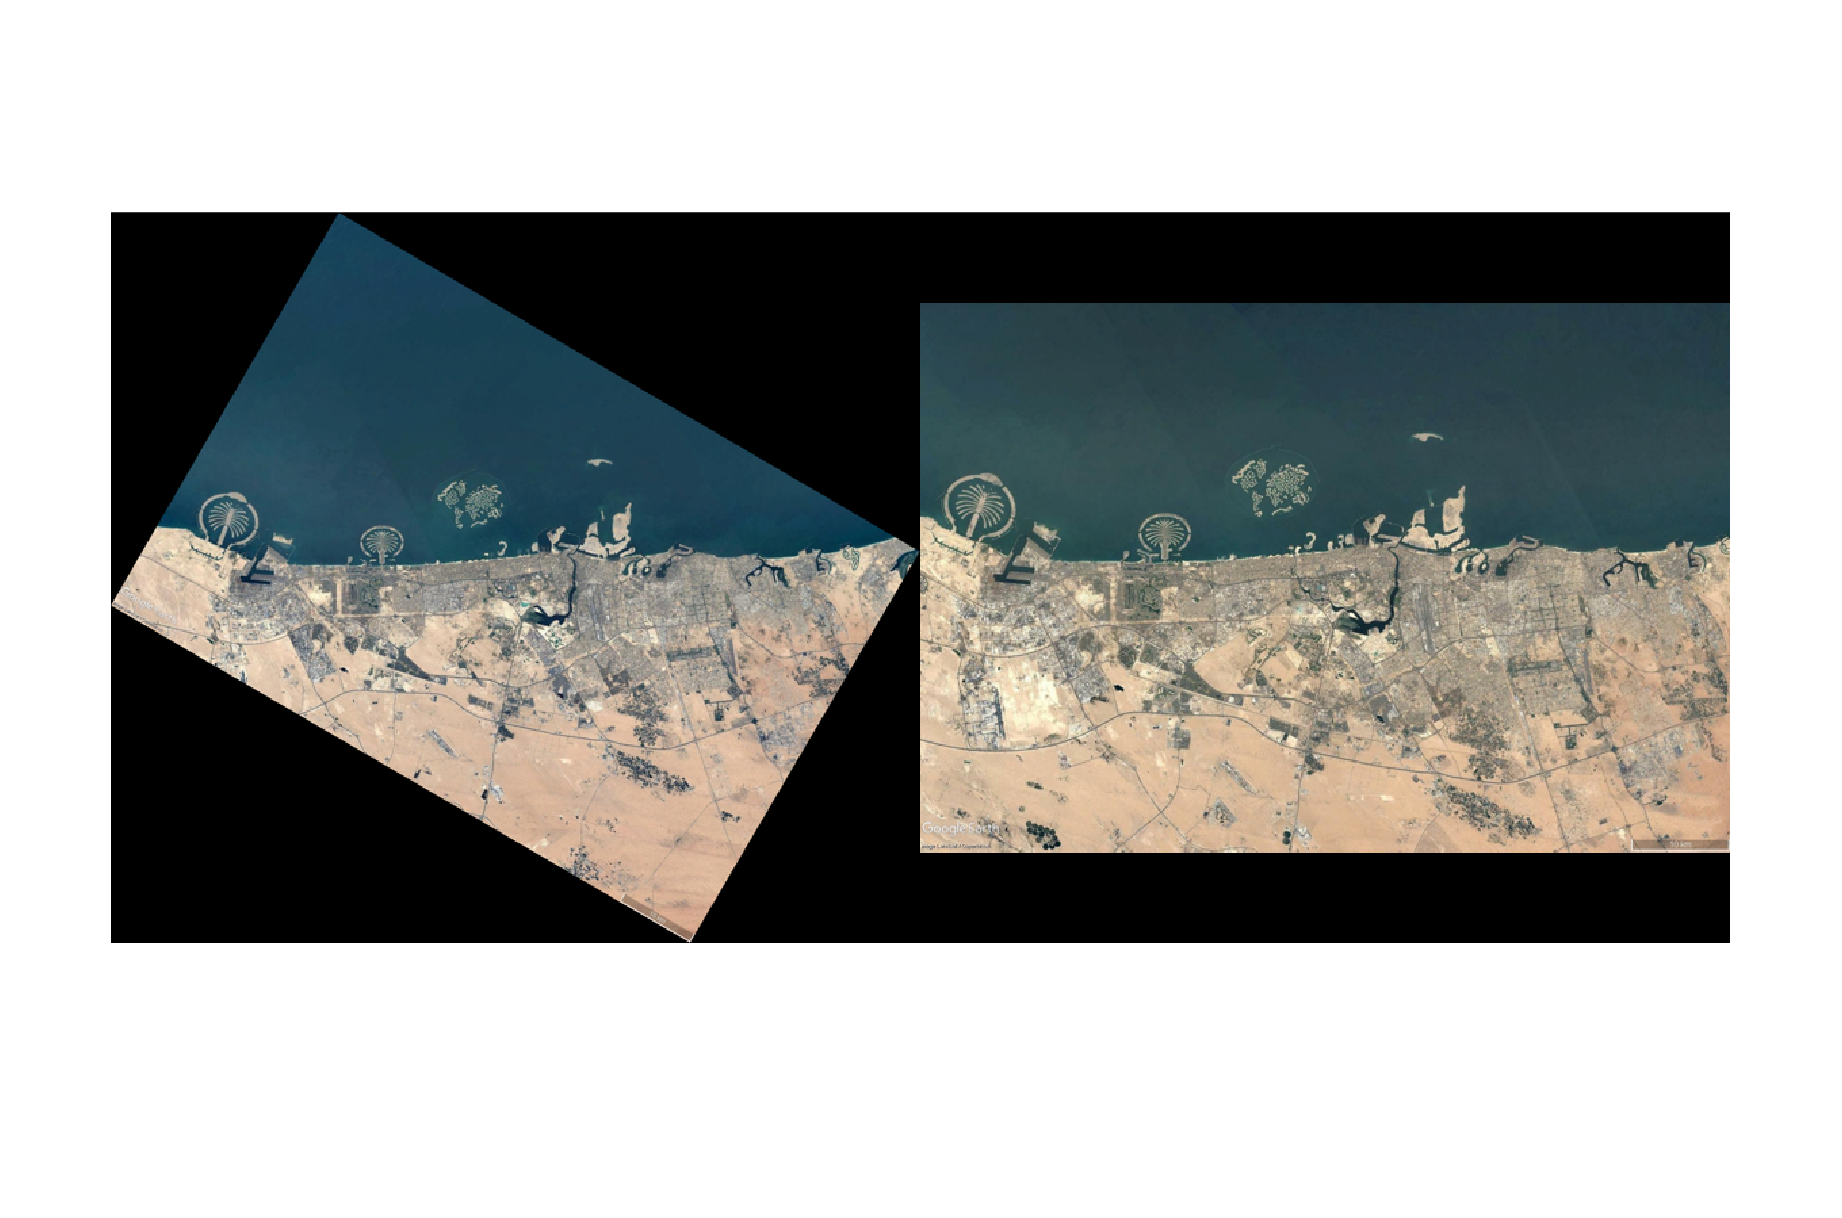

movingT = regOutput.Transformation;
movingWarped = imwarp(movingImg,movingT);
 
montage({movingWarped, fixedImg})

movingMask = createDubaiCityMask(movingWarped);
fixedMask =createDubaiCityMask(fixedImg);
montage({movingMask,fixedMask})

% --- Count non-zero (foreground) pixels in each mask --------------------
numFixed  = nnz(fixedMask);     % # pixels in the reference (fixed) mask
numMoving = nnz(movingMask);    % # pixels in the registered/segmented (moving) mask

% --- Compute the relative difference as a percentage -------------------
diffPercent = (numFixed - numMoving) / numFixed * 100;

% --- Print the results to the Command Window ---------------------------
fprintf('Fixed mask  : %d pixels\n',  numFixed);

Fixed mask  : 164759 pixels


fprintf('Moving mask : %d pixels\n',  numMoving);

Moving mask : 152370 pixels


fprintf('The city has grown by about  : %.2f %%\n',    diffPercent);

The city has grown by about  : 7.52 %
